**Multiobjective Optimization**

Consider the linear multiobjective problem:


$$\left\lbrace \begin{array}{ll}
\textrm{minimize} & \left(x_1 +2x_2 -3x_3 \right),\left({-x}_1 -x_2 -x_3 \right),\left(-4x_1 -2x_2 +x_3 \right)\\
\textrm{subject}\;\textrm{to} & x_1 +x_2 +x_3 \le 10\\
\; & x_3 \le 5\\
\; & -x_1 \le 0\\
\; & -x_2 \le 0\\
\; & -x_3 \le 0
\end{array}\right.$$
 

Check if the points u = (5, 0, 5), v = (4, 4, 2) and w = (1, 4, 4) are minima or weak minima by solving the corresponding auxiliary problems.

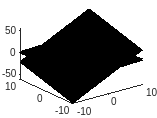

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

x1 = -10:0.1:10;
x2 = -10:0.1:10;

[X1,X2] = meshgrid(x1,x2);

X3 = (X1+2.*X2)/3;
X4 = (-X1-X2);
X5 = (4.*X1+2.*X2);
surface(X1,X2,X3, 'FaceAlpha',0.5);
hold on
surface(X1,X2,X4,'FaceAlpha',0.2);
surface(X1,X2,X5, 'FaceAlpha',0.7);
view(3);
hold off

% Environment Variables
C = [ 1  2 -3
     -1 -1 -1
     -4 -2  1];

A = [ 1  1  1
      0  0  1
     -1  0  0
      0 -1  0
      0  0 -1];

b = [10
      5
      0
      0
      0];

u = [5
     0
     5];

v = [4
     4
     2];

w = [1
     4
     4];

z = [3
     3
     4];

y = z;

% Variables number
n = size(C,2);
% Functions number
p = size(C,1);
% Constraints number
m = size(A,1);

% Calculate the linear Problem

c = [zeros(n,1)
    -ones(p,1)];

P = [C           eye(p)
     A           zeros(m,n)
     zeros(p,n) -eye(p)];

q = [C*y
     b
     zeros(p,1)];

% Solve the Linear Programming check minimum
options = optimset('Display', 'off');
[~, minimum] = linprog(c,P,q, [],[],[],[],options)

minimum = -9.7500


% Solve the Linear Programming check weak minimum

c = [zeros(n,1)
     zeros(p,1)
     -1];

P = [zeros(p,n)  -eye(p)    ones(p,1)
     C           eye(p)     zeros(p,1)
     A           zeros(m,n) zeros(m,1)
     zeros(p,n) -eye(p)     zeros(p,1)];

q = [zeros(p,1)
     C*y
     b
     zeros(p,1)];


[~, minimum_weak] = linprog(c,P,q, [],[],[],[],options)

minimum_weak = 0

**Alternative and Manual verification**

Check the point $x^{\star } =\left(5,0\ldotp 5\right)$

Calculate $f\left(x^{\star } \right)$

x1 = 5;
x2 = 0;
x3 = 5;

f1 = x1+2.*x2-3.*x3;
f2 = -x1-x2-x3;
f3 = -4.*x1-2.*x2+x3;

f_xopt = [f1 f2 f3]

f_xopt =    -10   -10   -15


The corresponding auxiliary problem with $f\left(x^{\star } \right)=\left(-10,-10,-15\right)$


$$\left\lbrace \begin{array}{lll}
-\textrm{minimize} & -v & \\
s\ldotp t & x_1 +2x_2 -3x_3 +\varepsilon_1  & \le -10\\
 & -x_1 -x_2 -x_3 +\varepsilon_2  & \le -10\\
 & -4x_1 -2x_2 +x_3 +\varepsilon_3  & \le -15\\
 & x_1 +x_2 +x_3  & \le 10\\
 & x_3  & \le 5\\
 & x_1 \ldotp x_2 ,x_3  & \ge 0\\
 & \varepsilon_1 ,\varepsilon_2 ,\varepsilon_3  & \ge 0\\
 & -v & \le \varepsilon_i 
\end{array}\right.$$


A = [ 1  2 -3  1  0  0  0
     -1 -1 -1  0  1  0  0
     -4 -2  1  0  0  1  0
      1  1  1  0  0  0  0
      0  0  1  0  0  0  0
      0  0  0 -1  0  0  0
      0  0  0  0 -1  0  0
      0  0  0  0  0 -1  0
     -1  0  0  0  0  0  1
      0 -1  0  0  0  0  1
      0  0 -1  0  0  0  1];

b = [-10
     -10
     -15
      10 
       5
       0 
       0
       0
       0
       0
       0];

f = [0
     0
     0
     0
     0
     0
    -1];

lb = [0
      0
      0
      0
      0
      0
     -inf];

[x, fval] = linprog(f,A,b, [], [], lb);

Optimal solution found.



x

x =     5.0000
         0
    5.0000
         0
         0
         0
         0


fval

fval = 0

f = [ 0
      0
      0
     -1
     -1
     -1];

b = [-10
     -10
     -15
      10
      5];

A = [  1  2 -3  1  0  0
      -1 -1 -1  0  1  0
      -4 -2  1  0  0  1
       1  1  1  0  0  0
       0  0  1  0  0  0];

lb = zeros(6,1);



[x, fval] = linprog(f,A,b, [],[],lb);

Optimal solution found.




x

x =      5
     0
     5
     0
     0
     0


fval

fval = 0

C = [ 1  2 -3
     -1 -1 -1
     -4 -2  1];

y = [3
     3
     4]

y =      3
     3
     4



fx = C*y

fx =     -3
   -10
   -14


A = [ 1  1  1
      0  0  1
     -1  0  0
      0 -1  0
      0  0 -1];

b = [10
      5
      0
      0
      0];

% Variables number
n = size(C,2);
% Functions number
p = size(C,1);
% Constraints number
m = size(A,1);

% Calculate the linear Problem

c = [zeros(n,1)
    -ones(p,1)];

P = [C           eye(p)
     A           zeros(m,n)
     zeros(p,n) -eye(p)];

q = [C*y
     b
     zeros(p,1)];

% Solve the Linear Programming check minimum
options = optimset('Display', 'off');
[~, minimum] = linprog(c,P,q, [],[],[],[],options)

% Solve the Linear Programming check weak minimum

c = [zeros(n,1)
     zeros(p,1)
     -1];

P = [zeros(p,n)  -eye(p)    ones(p,1)
     C           eye(p)     zeros(p,1)
     A           zeros(m,n) zeros(m,1)
     zeros(p,n) -eye(p)     zeros(p,1)];

q = [zeros(p,1)
     C*y
     b
     zeros(p,1)];


[~, minimum_weak] = linprog(c,P,q, [],[],[],[],options)